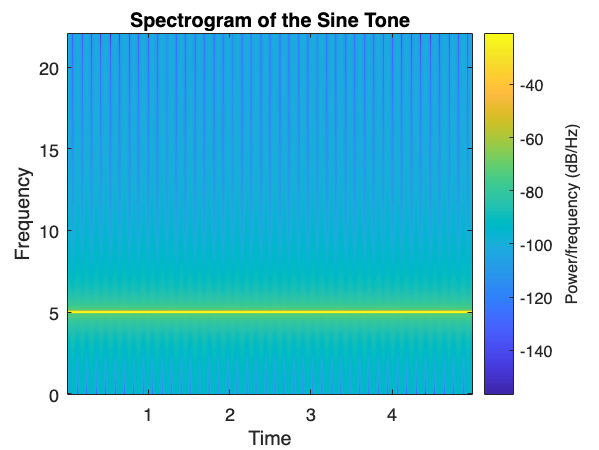

% Read WAV file
[audio, Fs] = audioread('1.wav');

% Duration of audio file
duration = length(audio) / Fs;

% Time vector
t = linspace(0, duration, length(audio));

% Frequency of the sine tone
f = 5000;

% Make the sine tone
sine_tone = sin(2 * pi * f * t);
        
% Play the sine tone
sound(sine_tone, Fs);

% Save to WAV file
filename = 'Carrion-sinetone.wav';
audiowrite(filename, sine_tone, Fs);

% Plot spectrogram of the sine tone
spectrogram(sine_tone, 1024, 512, [], Fs, 'yaxis');
title('Spectrogram of the Sine Tone');
xlabel('Time');
ylabel('Frequency');


% Save spectrogram
saveas(gcf, 'sine_tone_spectrogram.png');